**Load golf ball data**

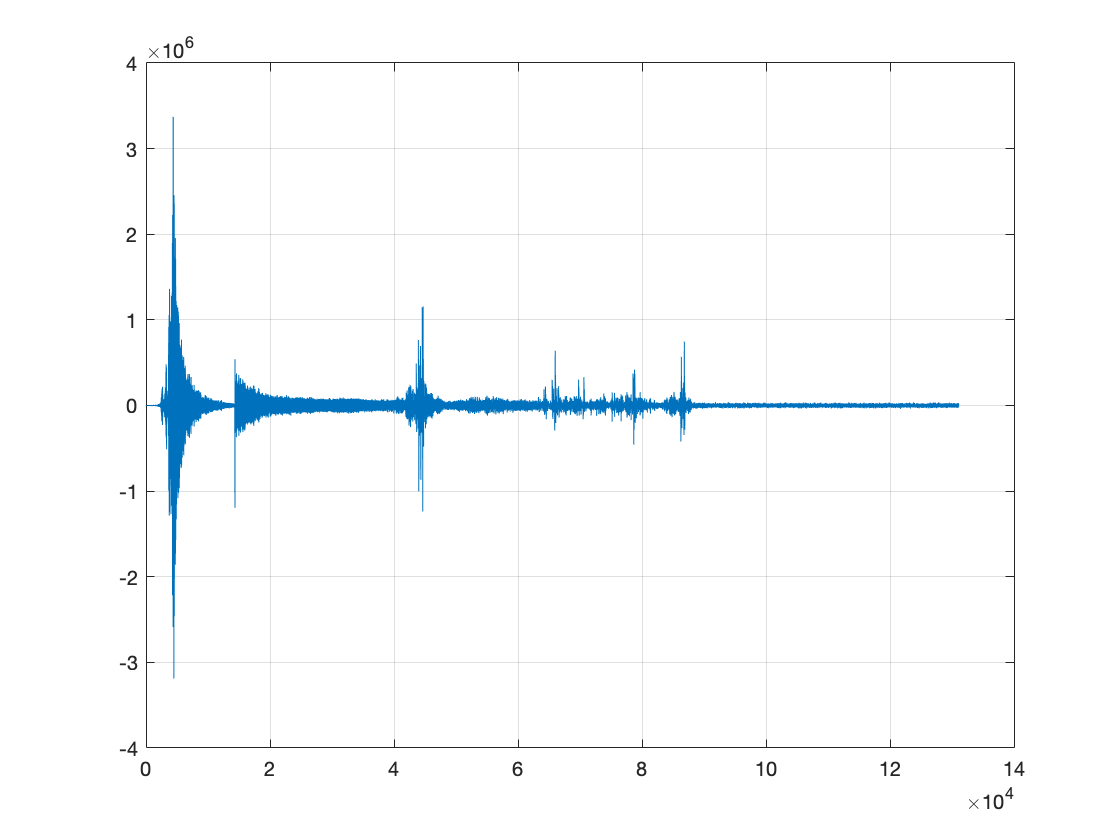

close all;
clear;

% Load golf shot data
filename = 'wedge_shot.txt';
AllData = fileread(filename);
[~, beg_idx] = regexp(AllData,':'); % start extracting data after ':' character is found 
AllData = AllData(beg_idx+1:end);
AllData = textscan(AllData,'%s');
GolfBallData = str2double(AllData{1}); % Data values has all the data values from the .txt file 

figure; plot(GolfBallData); grid on; 

**Parameters:**

fs = 17045; %Sampling freq
nfft = 8192; %FFT length
L = 1217; %Window length
overlap = floor(0.85*L); % 85% overlap
N = 0; % User-defined. Used for adaptive threshold later.

**Signal data:**

% SIGNAL
signal = GolfBallData;

**Applying a HPF:**

% Load HPF
load('HPF.mat')

% Filter designed using filter designer app in MATLAB
A = floor(length(Num)/2);
signal = conv(signal,Num);
signal = signal(A:end-A);

**Calling Spectrogram function:**

%Spectrogram 

W = kaiser(L,8);
[Spec_t,freq,Spec_mag,Spec] = spectrogram_function(signal,W,overlap,nfft,fs);
[f_bins,nframes] = size(Spec_mag); % Number of freq bins and frames

**Adaptive threshold using modal intensity + N*(std. dev.):**

hist_length = floor(f_bins/8); % Length hist = 1/8 of num. frames
modal_intensity = zeros(1,nframes);

for i = 1:nframes
    
    frame = Spec_mag(:,i); %Current time frame
    
    [hist,edges] = histcounts(frame,hist_length); %Get histogram counts and edges
    hist_smooth = movmean(hist,5); % Smooth with 5-pt moving avg filter
    index_modal_intensity = find(hist_smooth == max(hist_smooth)); %Index for modal intensity
    index_modal_intensity = index_modal_intensity(1); %Choose first index if max is over multiple bins
    modal_intensity(i) = (edges(index_modal_intensity)+edges(index_modal_intensity+1))/2; %Find corresponding intensity
    smooth_modal_intensity = movmean(modal_intensity,5); %Smooth noise profile
    
    threshold = smooth_modal_intensity(i) + N*std(frame); %Set threshold for current time frame
    
    for j = 1:f_bins
       if frame(j) < threshold %If element in frame is less than threshold then set to -100 dB
           frame(j) = 0;
       end
    end
   
    Spec_mag(:,i) = frame;
end


**Plotting Spectrogram:**

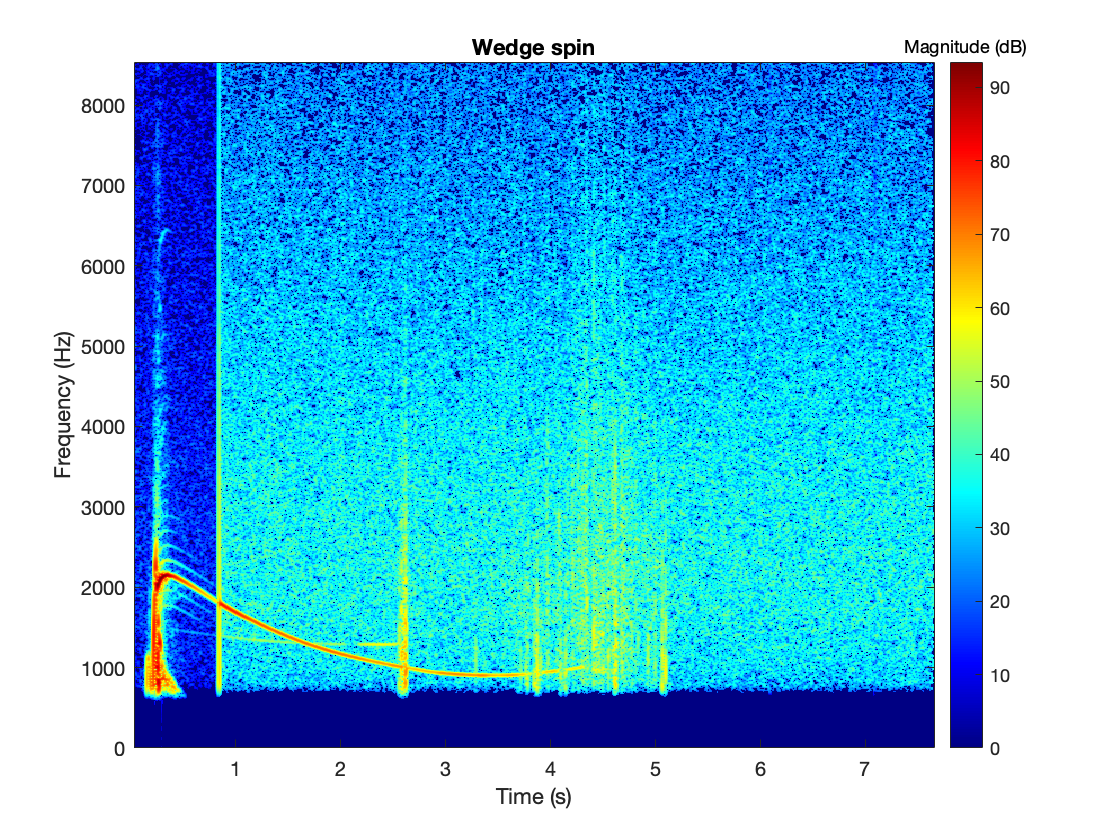

%Plotting Spectrogram

imagesc(Spec_t,freq,Spec_mag);
set(gca,'YDir','normal') % Flip y-axis such that 0 kHz is at the bottom
h = colorbar; % Create colour bar showing magnitude
colormap('jet')
set(get(h,'title'),'string','Magnitude (dB)'); % Label colourbar
title("Wedge spin"), xlabel("Time (s)"),ylabel("Frequency (Hz)")

**Spin tracking:**

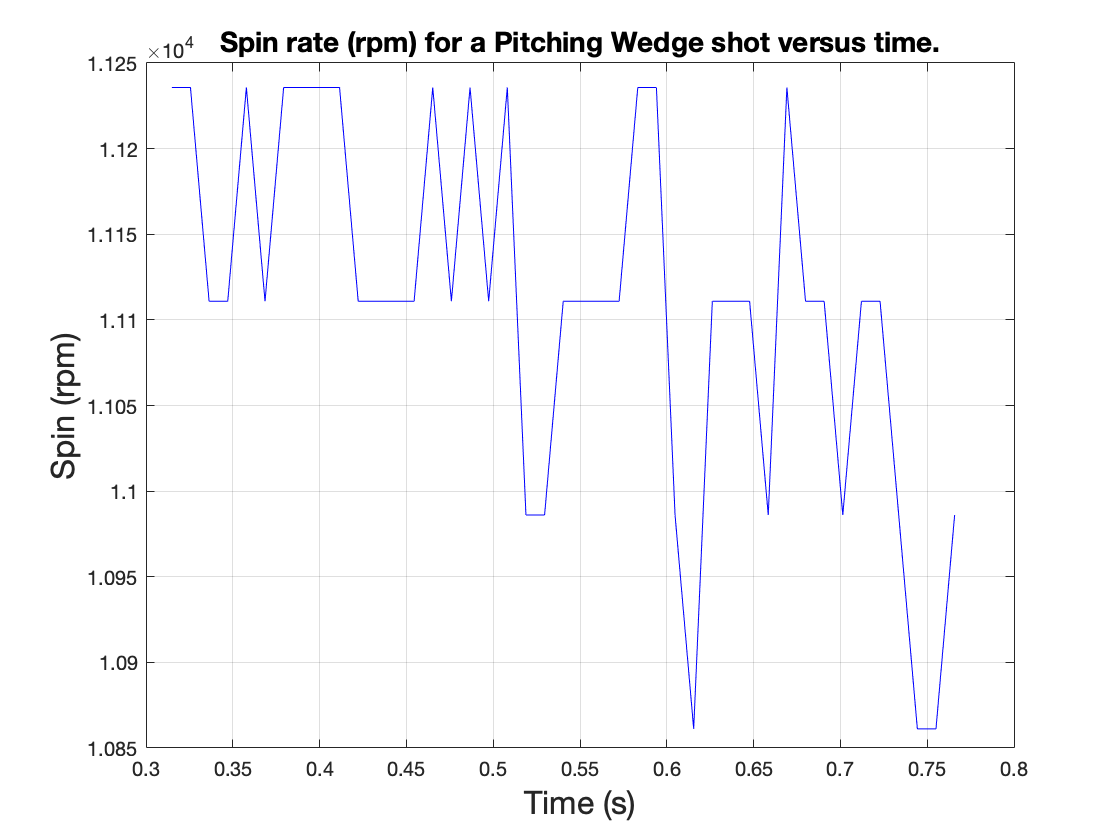

frame_width = (length(signal)/nframes); 
start_of_spin = floor(((0.3*fs)/frame_width));
end_of_spin = floor(((0.75*fs)/frame_width));

Spin_Hz = zeros(1,(end_of_spin-start_of_spin+1));
% 
for i = start_of_spin:end_of_spin
    
    frame1 = Spec_mag(:,i);
    
    [pks,locs] = findpeaks(Spec_mag(:,i),'MinPeakHeight',25,'MinPeakDistance',100*(nfft/fs));
   
    index_max_pk = find(pks == max(pks));
    if index_max_pk < length(locs)
        Spin_Hz(i-start_of_spin+1) = (locs(index_max_pk+1) - locs(index_max_pk)).*(fs/nfft);
    else
        Spin_Hz(i-start_of_spin+1) = (locs(index_max_pk) - locs(index_max_pk-1)).*(fs/nfft);
    end
    
end

plot(Spec_t(start_of_spin:end_of_spin),Spin_Hz*60,'b-');
title("Spin rate (rpm) for a Pitching Wedge shot versus time.",'FontSize', 14);
xlabel("Time (s)",'FontSize', 16);
ylabel("Spin (rpm)",'FontSize', 16);
grid on;

**Frequency spectrum at 0.3578 seconds:**

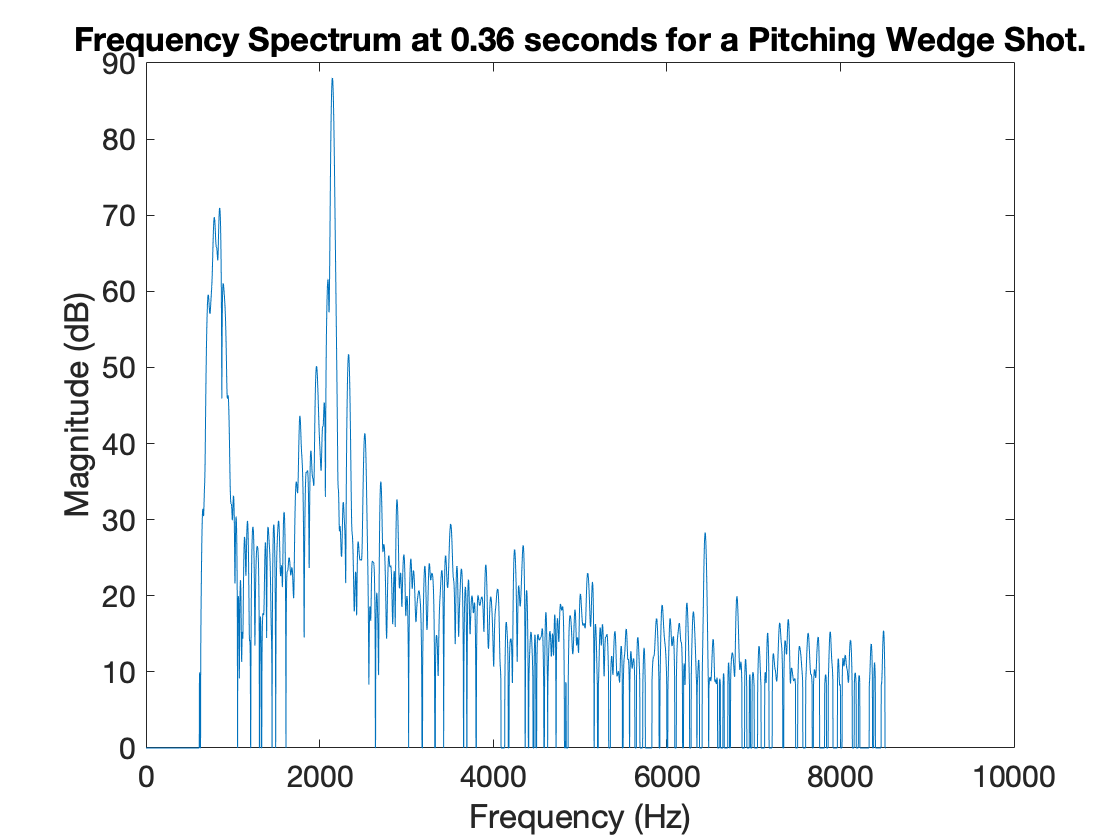

plot(freq,Spec_mag(:,31));
title("Frequency Spectrum at 0.36 seconds for a Pitching Wedge Shot.",'FontSize', 16);
xlabel("Frequency (Hz)",'FontSize', 16);
ylabel("Magnitude (dB)",'FontSize', 16);
set(gca,'FontSize',15);